# Taller Robotica Teoria

## Juan Pablo Arango - Geronimo Bustos Pinzon - Juan Esteban Gil

## **1803716 - 1803609 -1803603**

- **Considere una orientación especificada por las secuencias de ángulos definidas por la secuencia de ángulos siguiente alrededor de ejes fijos: α alrededor de X, β alrededor de Z, y γ alrededor de X Determine todos los sets de ángulos (α, β, γ) que definen la orientación especificada por**

syms alpha beta gamma
a=alpha; b=beta; g=gamma;
R=[ 0.5000   -0.6124    0.6124;

    0        -0.7071    -0.7071;

    0.8660    0.3536   -0.3536]; %% Specified matrix

Rx=[1   0        0;
    0 cos(a) -sin(a) ;
    0 sin(a)  cos(a) ];

Rz=[cos(b) -sin(b) 0;
    sin(b)  cos(b) 0;
    0          0     1];
Rx2=[1   0        0;
    0 cos(g) -sin(g) ;
    0 sin(g)  cos(g) ];
Rsymb= expand(Rx2*Rz*Rx) %% fixed frame pre multiplication

$$Rsymb = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\cos\left(\alpha \right)\,\sin\left(\beta \right) & \sin\left(\alpha \right)\,\sin\left(\beta \right)\\ \cos\left(\gamma \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\gamma \right) & -\cos\left(\alpha \right)\,\sin\left(\gamma \right)-\cos\left(\beta \right)\,\cos\left(\gamma \right)\,\sin\left(\alpha \right)\\ \sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)+\cos\left(\alpha \right)\,\cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\cos\left(\beta \right)\,\sin\left(\alpha \right)\,\sin\left(\gamma \right) \end{array}\right)$$

**De la matriz se puede observar que:**

- $0\ldotp 5=C_{\beta }$*** , por lo tanto, ***$S_{\beta } =\pm \sqrt{1-{\left(C_{\beta } \right)}^2 \;}$ **de R11**

- **De R21 y R31 **$\tan \left(\gamma \right)=\frac{\mathrm{R31}}{\mathrm{R21}}=\frac{\sin \left(\gamma \right)}{\cos \left(\gamma \right)}$ **, por lo que, **$\gamma =\textrm{atan}\left(\frac{\textrm{R31}}{\textrm{R21}}\right)$

- **De R12 y R13 **$-\tan \left(\alpha \right)=\frac{\textrm{R13}}{\textrm{R12}}=\frac{\sin \left(\alpha \right)}{\cos \left(\alpha \right)}$ **, por lo que, **$\alpha =\mathrm{atan}\left(-\frac{\mathrm{R13}}{\mathrm{R12}}\right)$

## Set $\phi_1$ 

alpha_1=atan2d(R(1,3),-R(1,2))

alpha_1 = 45

beta_1=atan2d(sqrt(1-(0.5)^2),0.5)

beta_1 = 60.0000

gamma_1=atan2d(R(3,1),R(2,1))

gamma_1 = 90

## Set $\phi_2$ 

alpha_2=atan2d(R(1,3),-R(1,2))

alpha_1 = 45

beta_2=atan2d(-sqrt(1-(0.5)^2),0.5)

beta_1 = -60.0000

gamma_2=atan2d(R(3,1),R(2,1))

gamma_1 = 90

2.** Considere una orientación especificada por las secuencias de ángulos definidas por la secuencia de ángulos siguiente alrededor de ejes actuales: α alrededor de X, β alrededor de Z, y γ alrededor de X Determine todos los sets de ángulos (α, β, γ) que definen la orientación especificada por**

syms alpha beta gamma

$$Rsymb = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\cos\left(\gamma \right)\,\sin\left(\beta \right) & \sin\left(\beta \right)\,\sin\left(\gamma \right)\\ \cos\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\gamma \right) & -\cos\left(\gamma \right)\,\sin\left(\alpha \right)-\cos\left(\alpha \right)\,\cos\left(\beta \right)\,\sin\left(\gamma \right)\\ \sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\beta \right)\,\cos\left(\gamma \right)\,\sin\left(\alpha \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\cos\left(\beta \right)\,\sin\left(\alpha \right)\,\sin\left(\gamma \right) \end{array}\right)$$

a=alpha; b=beta; g=gamma;
R=[ -0.6124  -0.5    0.6124;
     0.3536  -0.866 -0.3536;
     0.7071   0      0.7071]; %% Specified matrix

Rx=[1   0        0;
    0 cos(a) -sin(a) ;
    0 sin(a)  cos(a) ];

Rz=[cos(b) -sin(b) 0;
    sin(b)  cos(b) 0;
    0          0     1];
Rx2=[1   0        0;
    0 cos(g) -sin(g) ;
    0 sin(g)  cos(g) ];
Rsymb= expand(Rx*Rz*Rx2) %% Current frame post multiplication

**De la matriz se puede observar que:**

- $-0\ldotp 6124=C_{\beta }$*** , por lo tanto, ***$S_{\beta } =\pm \sqrt{1-{\left(C_{\beta } \right)}^2 \;}$ **de R11**

- **De R12 y R13 **$-\tan \left(\gamma \right)=\frac{\textrm{R13}}{\textrm{R12}}=\frac{\sin \left(\gamma \right)}{\cos \left(\gamma \right)}$ **, por lo que, **$\gamma =\textrm{atan}\left(-\frac{\textrm{R13}}{\textrm{R12}}\right)$

- **De R12 y R13 **$\tan \left(\alpha \right)=\frac{\textrm{R31}}{\textrm{R21}}=\frac{\sin \left(\alpha \right)}{\cos \left(\alpha \right)}$ **, por lo que, **$\alpha =\textrm{atan}\left(\frac{\textrm{R31}}{\textrm{R21}}\right)$

## Set $\phi_1$ 

alpha_1=atan2d(R(3,1),R(2,1))
beta_1=atan2d(sqrt(1-(0.6124)^2),-0.6124)

alpha_1 = 63.4317

gamma_1=atan2d(R(1,3),-R(1,2))

beta_1 = 127.7632

## Set $\phi_2$ 

alpha_2=atan2d(R(3,1),R(2,1))

gamma_1 = 50.7697

PHI =    63.4317  127.7632   50.7697


beta_2=atan2d(-sqrt(1-(0.6124)^2),-0.6124)
gamma_2=atan2d(R(1,3),-R(1,2))

alpha_1 = 63.4317

beta_1 = -127.7632

3. . **Considere los ángulos de Euler:**

 
$$\phi =\frac{\pi }{4}\;\theta =\frac{\pi }{3}\;\psi =-\frac{\pi }{6}\;$$


** a. Encuentre la matriz de rotación correspondiente al set de ángulos de Euler ZXZ**

syms phi theta psi

gamma_1 = 50.7697

a=phi; b=theta; g=psi;

Rz=[cos(a) -sin(a) 0;
    sin(a)  cos(a) 0;
    0          0   1];

Rx=[1   0        0;
    0 cos(b) -sin(b) ;
    0 sin(b)  cos(b) ];


Rz2=[cos(g) -sin(g) 0;
    sin(g)  cos(g)  0;
    0          0    1];
Rsymb= expand(Rz2*Rx*Rz) %% Fixed frame post multiplication
Rt= eval(subs(Rsymb,[a b g],[pi/4 pi/3 -pi/6]))

**b. Calcule los ángulos de Euler XZY (Considere las 2 soluciones) **

Rx=[1   0       0   ;
    0 cos(a) -sin(a);
    0 sin(a)  cos(a)];


$$Rsymb = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Ry=[cos(g) 0 -sin(g) ;

Rt =     0.7891   -0.4356   -0.4330
   -0.0474    0.6597   -0.7500
    0.6124    0.6124    0.5000


    0      1    0     ;
    sin(g) 0  cos(g) ];


Rz=[cos(b) -sin(b) 0;
    sin(b)  cos(b)  0;
    0          0    1];
Rsymb= expand(Rx*Rz*Ry) %%Fixed Frame multiplication

**De la matriz se observa que:**

- $-\sin \left(\theta \right)=-0\ldotp 4356$ **por lo tanto, **$C_{\theta } =\pm \sqrt{1-{\left(S_{\theta } \right)}^2 \;}$**de R12**

- **De R11 y R13 se observa que **$-\tan \left(\psi \right)=\frac{\sin \left(\psi \;\right)}{\cos \left(\psi \;\right)}=\frac{\mathrm{R13}}{\mathrm{R11}}$, **por lo que, **$\psi =\mathrm{atan}\left(-\frac{\mathrm{R13}}{\mathrm{R11}}\right)$

- **De R22 Y R32 se observa que **$\tan \left(\phi \;\right)=\frac{\sin \left(\phi \;\right)}{\cos \left(\phi \;\right)}=\frac{\mathrm{R32}}{\mathrm{R22}}$**, por lo que, **$\phi =\mathrm{atan}\left(\frac{\mathrm{R32}}{\mathrm{R22}}\right)$

## Set $\phi_1$ 

theta_1=atan2d(0.4356,sqrt(1-(sin(0.4356)^2)))
psi_1=atan2d(Rt(1,3),-Rt(1,1))
phi_1=atan2d(Rt(3,2),Rt(2,2))

## Set $\phi_2$ 

theta_2=atan2d(0.4356,-sqrt(1-(sin(0.4356)^2)))

$$Rsymb = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) \end{array}\right)$$

psi_2=atan2d(Rt(1,3),-Rt(1,1))
phi_2=atan2d(Rt(3,2),Rt(2,2))

**c. Escriba la representación eje ángulo R(r, **$\theta \;$**) de la matriz obtenida en el punto 3.a **

thetat=acos((Rt(1,1)+Rt(2,2)+Rt(3,3)-1)/2)%%Working with rads

theta_1 = 25.6628

r=(1/2*sin(thetat))*[Rt(3,2)-Rt(2,3);

psi_1 = -151.2461

                     Rt(1,3)-Rt(3,1);

phi_1 = 42.8676

                     Rt(2,1)-Rt(1,2)]

**d. Escriba la representación en cuaternios**

eta=(1/2)*sqrt(Rt(1,1)+Rt(2,2)+Rt(3,3)+1)

theta_1 = 154.3372

epsilon=(1/2)*[sign(Rt(3,2)-Rt(2,3))*sqrt(Rt(1,1)-Rt(2,2)-Rt(3,3)+1);

psi_1 = -151.2461

               sign(Rt(1,3)-Rt(3,1))*sqrt(Rt(2,2)-Rt(3,3)-Rt(1,1)+1);

phi_1 = 42.8676

               sign(Rt(2,1)-Rt(1,2))*sqrt(Rt(3,3)-Rt(2,2)-Rt(1,1)+1)]

thetat = 1.0765

r =     0.5996
   -0.4601
    0.1709


eta = 0.8586

epsilon =     0.3967
   -0.3044
    0.1130


4. **El dedo índice de esta mano tiene 4 grados de libertad rotacionales (dos en la base y otros dos para flexión y extensión de las falanges). Se puede asumir que cada juntura se actúa de forma independiente. El marco de referencia se asocia a la base del dedo, en la palma de la mano como se muestra:**

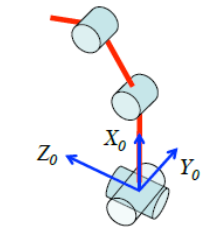

**a. Asigne los marcos según la convención DH y defina la tabla de parámetros.**

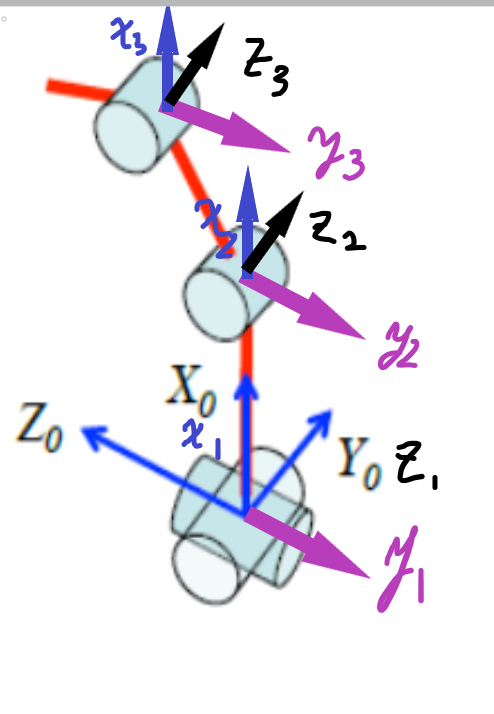

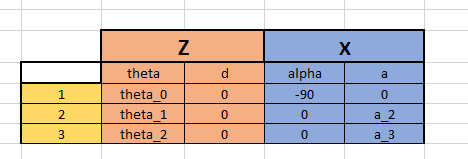

5. **Para el robot RPRP de la figura, Asigne los marcos de referencia y elabore la tabla de parámetros Denavit-Hartemberg. El origen del último marco coincide con el punto P. Utilice la menor cantidad de parámetros constantes posibles**

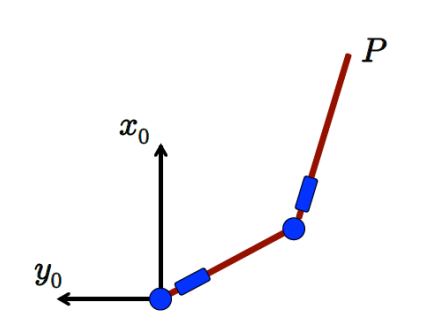

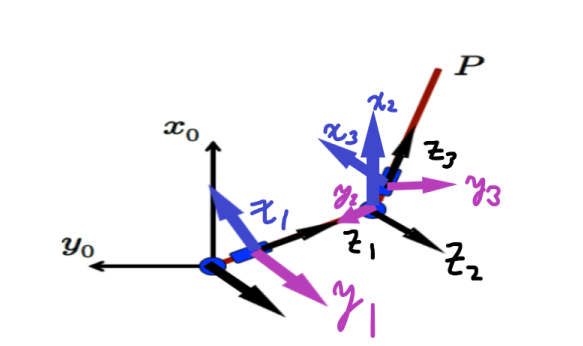

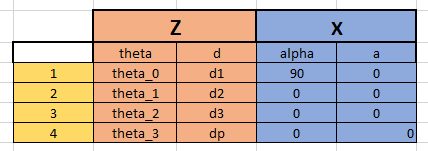

6.   ** Para el manipulador de 5 DoF RPP-RR de la figura, asigne los marcos de referencia y elabore la tabla de parámetros DH. El marco de referencia cero está en la base del robot y elija el último marco tal que d5 = 0**